# Elaborato di Calcolo Numerico: Gradiente Coniugato e Smoothing dei dati

Nel seguente elaborato si vogliono mostrare alcuni campi di applicazione del metodo del gradiente coniugato. Si è scelto di evidenziare come il metodo si presta per la risoluzione dei sistemi dei minimi quadrati, nell'ambito di algoritmi di Machine Learning.

## 1. Regressione Lineare

Si è scelto di utilizzare un dataset contenente numerose informazioni relative ad automobili. L'obiettivo dell'analisi è quello di stimare il prezzo di un'automobile sulla base di alcune features.

In questo caso si è scelto come unica feature la cilindrata (engine size).

clear
clc

% Caricamento del dataset
dataset = readtable('auto.csv');

% Estrazione della feature
x_points = table2array(dataset(:,'engine_size'))';

% Estrazione del target
y_points = str2double(table2array(dataset(:,'price')))';

% Data cleaning
x_points(isnan(x_points)) = mean(rmmissing(x_points));
y_points(isnan(y_points)) = mean(rmmissing(y_points));
y_points = y_points/1000;

Come è possibile osservare, esiste una correlazione positiva tra la cilindrata e il prezzo di un'auto.

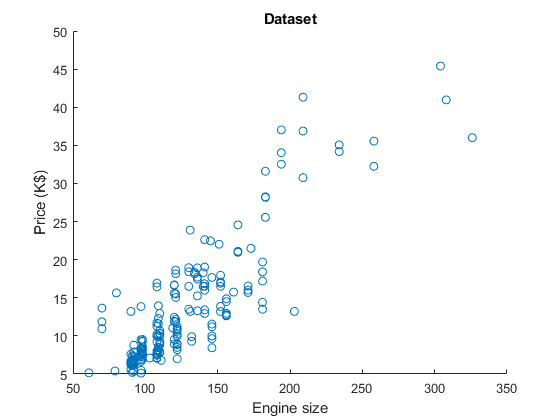

scatter(x_points, y_points)
title('Dataset')
xlabel('Engine size')
ylabel('Price (K$)')

### 1.1. Gradiente coniugato

Il modello è stato addestrato attraverso il metodo del gradiente coniugato.

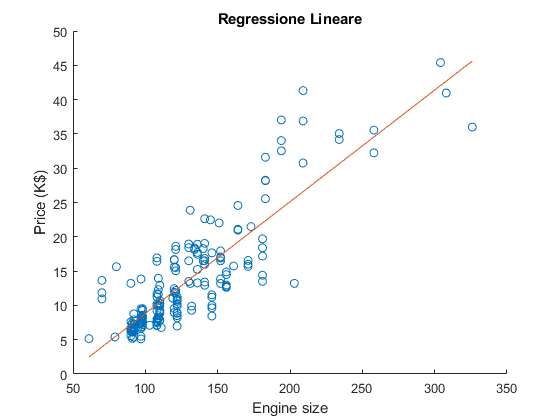

n = 1;              % ordine del polinomio
k_max = 100;        % numero massimo di iterazioni
toll = 1e-6;        % tolleranza richiesta
met = 'cg';         % metodo (gradiente o gradiente coniugato)
p0 = zeros(2,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p,res,iter,pvec,resvec] = poly_reg(x_points,y_points,n,k_max,toll,met,p0);

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Lineare')
xlabel('Engine size')
ylabel('Price (K$)')

Completato l'addestramento del modello, vengono restituiti i coefficienti della retta dei minimi quadrati, conentuti nel vettore p.

p

p =     0.1628
   -7.4579


 Ottenuti i coefficienti, è possibile stimare il prezzo di un'auto non contenuta all'interno del dataset fornendo in ingresso al modello la sua cilindrata.

x_hat = 280;
y_hat = polyval(p,x_hat)

y_hat = 38.1361

### 1.2. Analisi dell'algoritmo

Di seguito è possibile osservare l'andamento della norma dei residui calcolati durante l'esecuzione del metodo del gradiente, al variare del numero di iterazioni. Evidentemente, il metodo converge alla tolleranza specificata in sole due iterazioni. Ciò è dovuto al fatto che la matrice del sistema normale presenta due autovalori distinti.

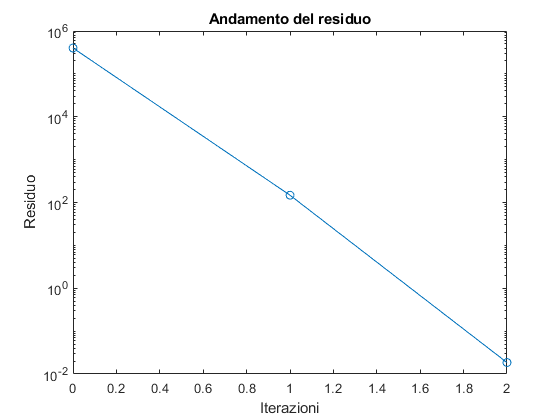

iter = 0:1:iter;
semilogy(iter,resvec,'-o')
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('Residuo')

Si può osservare come la retta dei minimi quadrati evolve durante l'esecuzione dell'algoritmo. Ad ogni iterazione l'algoritmo calcola una stima sempre più precisa della soluzione.

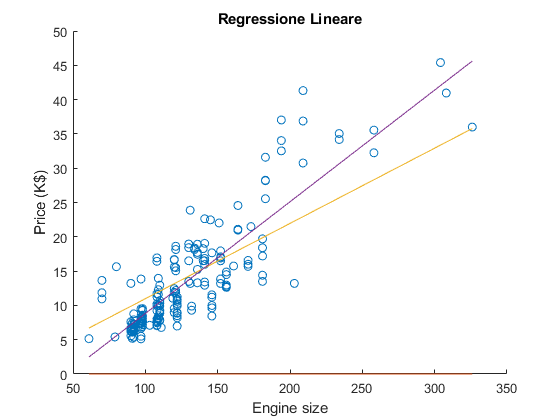

scatter(x_points, y_points)
hold on
x = min(x_points):0.1:max(x_points);
for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off
title('Regressione Lineare')
xlabel('Engine size')
ylabel('Price (K$)')

L'addestramento del modello consiste di fatto nel determinare il minimo della funzione $f\left(x\right)$, il cui andamento è descritto dal paraboloide riportato di seguito.

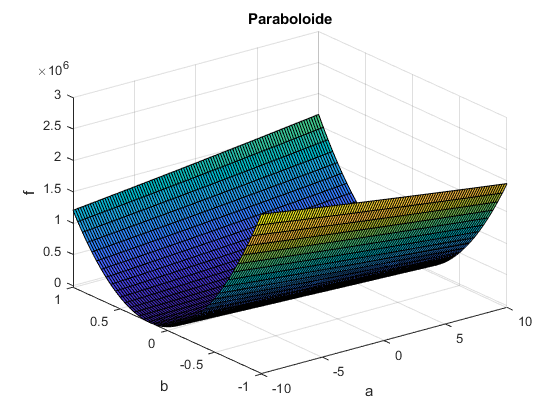

m = size(x_points,2);   % numero di campioni
n_pol = 1;              % ordine del polinomio
n = n_pol+1;
    
% Sistema normale
A = zeros(m,n);
for k=1:m
    for j=1:n
        A(k,j) = x_points(k)^(j-1);
    end
end
B = A'*A;
d = A'*y_points';

x1 = -10:0.2:10;
x2 = -1:0.05:1;
[X1,X2] = meshgrid(x1,x2);

f = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);

surf(X1,X2,f)
title('Paraboloide')
xlabel('a')
ylabel('b')
zlabel('f')

Riportando le soluzioni restituite dall'algoritmo sul piano del dominio del paraboloide, è possibile osservare come avviene la ricerca del minimo. Il metodo del gradiente genera una serie di punti spostandosi lungo le direzioni A-ortogonali di massima discesa. Tali direzioni coincidono con le direzioni degli assi delle ellissi rappresentanti le curve di livello di $f\left(x\right)$.

x1 = -10:0.2:10;
x2 = -1:0.05:1;
[X1,X2] = meshgrid(x1,x2);

f = (1/2)*(B(1,1)*X1.^2+(B(1,2)+B(2,1))*X1.*X2+B(2,2)*X2.^2)-(d(1)*X1+d(2)*X2);

contour(X1,X2,f);
hold on
points = flip(pvec,1);
for k=1:size(points,2)
    scatter(points(1,k),points(2,k)); 
end
for k=1:size(points,2)-1
    P1 = points(:,k);
    P2 = points(:,k+1);
    D = P2-P1;
    arrow3(P1',P2','-r',1,1)
end

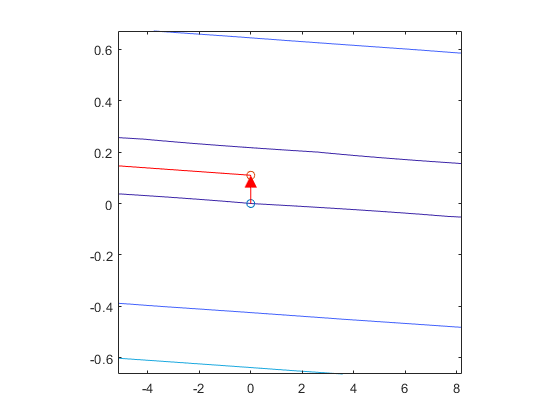

hold off

### 1.3. Confronto con il metodo del gradiente 

Si riporta un confronto tra il metodo del gradiente coniugato ed il metodo di discesa del gradiente tradizionale. 

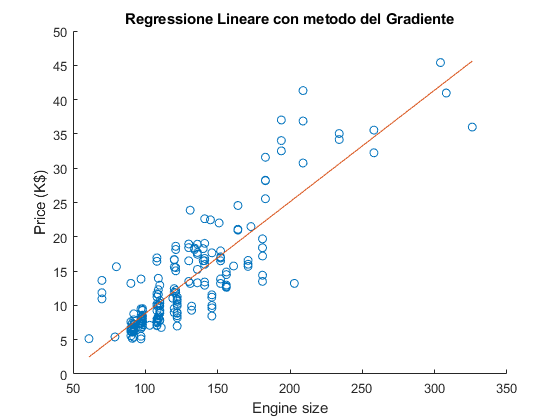

n = 1;              % ordine del polinomio
k_max = 100;        % numero massimo di iterazioni
toll = 1e-6;        % tolleranza richiesta
met = 'g';          % metodo (gradiente o gradiente coniugato)
p0 = zeros(2,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p_g,res_g,iter_g,pvec_g,resvec_g] = poly_reg(x_points,y_points,n,k_max,toll,met,p0);

x = min(x_points):0.1:max(x_points);
y = polyval(p_g,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Lineare con metodo del Gradiente')
xlabel('Engine size')
ylabel('Price (K$)')

La principale differenza tra i due metodi sta nel fatto che mentre l'ultimo si sposta nella ricerca del minimo lungo le direzioni a due a due ortogonali, il primo si sposta lungo direzioni A-ortogonali. Tale differenza si traduce in una velocità di convergenza pù elevata nel caso del gradiente coniugato, in quanto si evita di ripercorrere direzioni già percorse nel corso della ricerca.

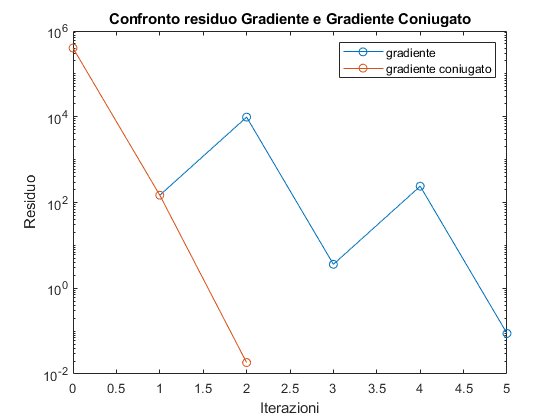

iter_g = 0:1:iter_g;
semilogy(iter_g,resvec_g,'-o')
hold on;
semilogy(iter,resvec,'-o')
hold off;

title('Confronto residuo Gradiente e Gradiente Coniugato')
legend('gradiente', 'gradiente coniugato')
xlabel('Iterazioni')
ylabel('Residuo')

contour(X1,X2,f);
hold on
points = flip(pvec,1);
for k=1:size(points,2)
    scatter(points(1,k),points(2,k)); 
end
for k=1:size(points,2)-1
    P1 = points(:,k);
    P2 = points(:,k+1);
    D = P2-P1;
    arrow3(P1',P2','-r',0.01,0.01)
end

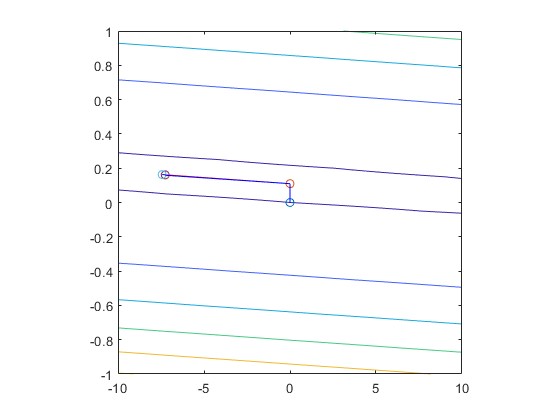

points1 = flip(pvec_g,1);
for k=1:size(points1,2)
    scatter(points1(1,k),points1(2,k)); 
end
for k=1:size(points1,2)-1
    P1 = points1(:,k);
    P2 = points1(:,k+1);
    D = P2-P1;
    arrow3(P1',P2','-b',0.01,0.01)
end
hold off

## 2. Regressione Polinomiale

Scegliendo come feature il numero di miglia per gallone (mpg) relativi a stade extra-urbane (highway-mpg) è possibile osservare una correlazione negativa tra consumi e il prezzo di un'auto. Tuttavia, in questo caso il legame tra variabile indipendente e variabile dipendente non segue una relazione lineare ma una polinomiale.

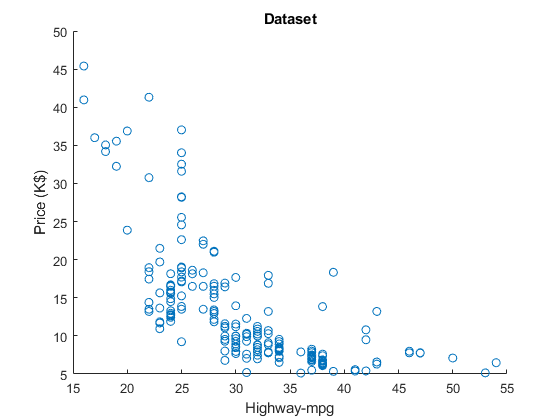

x_points = table2array(dataset(:,'highway_mpg'))';
y_points = str2double(table2array(dataset(:,'price')))';

% Data cleaning
x_points(isnan(x_points)) = mean(rmmissing(x_points));
y_points(isnan(y_points)) = mean(rmmissing(y_points));
y_points = y_points/1000;

scatter(x_points, y_points)
title('Dataset')
xlabel('Highway-mpg')
ylabel('Price (K$)')

Osservando l'andamento dei dati si è scelto di applicare un modello di regressione polinomiale del terzo ordine.

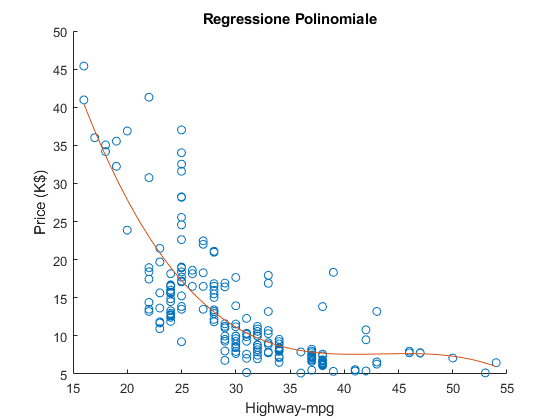

n = 3;              % ordine del polinomio
k_max = 100;        % numero massimo di iterazioni
toll = eps;         % tolleranza richiesta
met = 'cg';         % metodo (gradiente o gradiente coniugato)
p0 = zeros(4,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p,res,iter,pvec,resvec] = poly_reg(x_points,y_points,n,k_max,toll,met,p0);

x = min(x_points):0.1:max(x_points);
y = polyval(p,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Polinomiale')
xlabel('Highway-mpg')
ylabel('Price (K$)')

Completato l'addestramento del modello, vengono restituiti i coefficienti del polinomio dei minimi quadrati, conentuti nel vettore p.

p

p =    -0.0016
    0.2134
   -9.2256
  140.1578


Ottenuti i coefficienti, è possibile stimare il prezzo di un'auto non contenuta all'interno del dataset fornendo in ingresso al modello il numero di miglia per gallone.

x_hat = 45;
y_hat = polyval(p,x_hat)

y_hat = 7.6702

### 2.1. Analisi dei risultati

Di seguito è possibile osservare l'andamento della norma dei residui calcolati durante l'esecuzione del metodo del gradiente, al variare del numero di iterazioni. Evidentemente, il metodo converge in 12 iterazioni dal momento che la matrice ottenuta dalla costruzione del sistema normale risulta essere molto malcondizionata. 

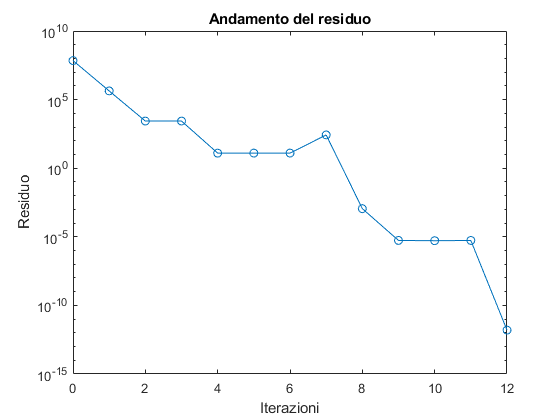

iter = 0:1:iter;
semilogy(iter,resvec,'-o')
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('Residuo')

Si può osservare come il polinomio dei minimi quadrati evolve durante l'esecuzione dell'algoritmo. Ad ogni iterazione l'algoritmo calcola una stima sempre più precisa della soluzione.

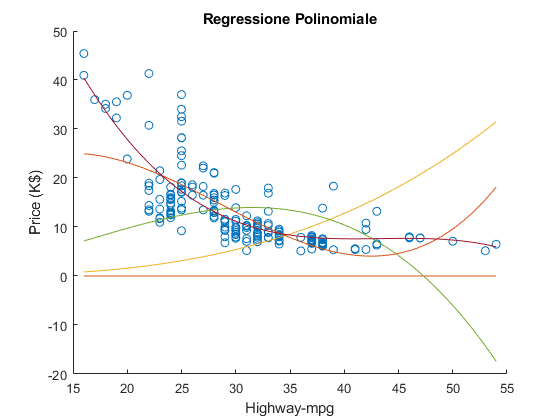

scatter(x_points, y_points)
hold on
x = min(x_points):0.1:max(x_points);
for k=1:size(pvec,2)
    y = polyval(pvec(:,k),x);
    plot(x,y)
end
hold off
title('Regressione Polinomiale')
xlabel('Highway-mpg')
ylabel('Price (K$)')

### 2.2. Confronto con il metodo del gradiente 

Si riporta un confronto tra il metodo del gradiente coniugato ed il metodo di discesa del gradiente tradizionale.

n = 3;              % ordine del polinomio
k_max = 100;        % numero massimo di iterazioni
toll = eps;         % tolleranza richiesta
met = 'g';          % metodo (gradiente o gradiente coniugato)
p0 = zeros(4,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p_g,res_g,iter_g,pvec_g,resvec_g] = poly_reg(x_points,y_points,n,k_max,toll,met,p0);

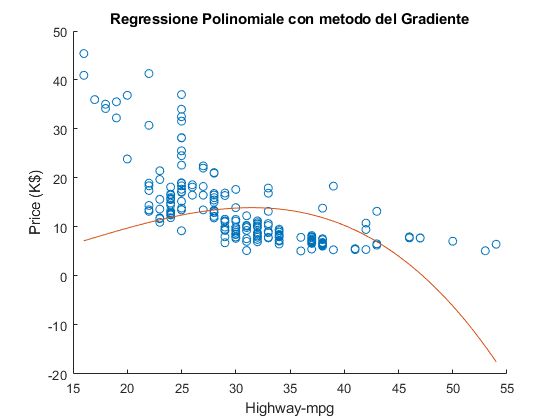


x = min(x_points):0.1:max(x_points);
y = polyval(p_g,x);
scatter(x_points, y_points)
hold on
plot(x,y)
hold off
title('Regressione Polinomiale con metodo del Gradiente')
xlabel('Highway-mpg')
ylabel('Price (K$)')

È possibile osservare che utilizzando il metodo del gradiente tradizionale l'algoritmo non converge.

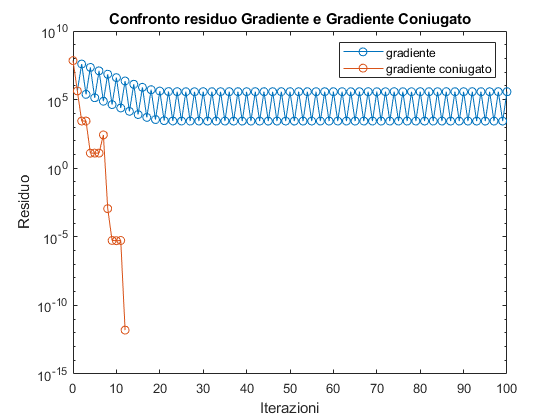

iter_g = 0:1:iter_g;
semilogy(iter_g,resvec_g,'-o')
hold on;
semilogy(iter,resvec,'-o')
hold off;

legend('gradiente', 'gradiente coniugato')
title('Confronto residuo Gradiente e Gradiente Coniugato')
xlabel('Iterazioni')
ylabel('Residuo')

## 3. Regressione Lineare Multipla

Una stima più precisa dei costi può essere ottenuta considerando più di una feature alla volta. Nel caso specifico si è scelto di considerare:

- Cavalli

- Peso

- Cilindrata

- Consumi (mpg) su strade extra-urbane

x1_temp = str2double(table2array(dataset(:,'horsepower')));
x2_temp = table2array(dataset(:,'curb_weight'));
x3_temp = table2array(dataset(:,'engine_size'));
x4_temp = table2array(dataset(:,'highway_mpg'));

% Data cleaning
x1 = x1_temp/max(x1_temp);
x2 = x2_temp/max(x2_temp);
x3 = x3_temp/max(x3_temp);
x4 = x4_temp/max(x4_temp);
x1(isnan(x1)) = mean(rmmissing(x1));
x2(isnan(x2)) = mean(rmmissing(x2));
x3(isnan(x3)) = mean(rmmissing(x3));
x4(isnan(x4)) = mean(rmmissing(x4));
x_points = [x1 x2 x3 x4];

y_points = str2double(table2array(dataset(:,'price')))';
y_points(isnan(y_points)) = mean(rmmissing(y_points));
y_points = y_points/1000;

Come è possibile osservare, tutte e 4 le features hanno una correllazione non nulla con il prezzo.

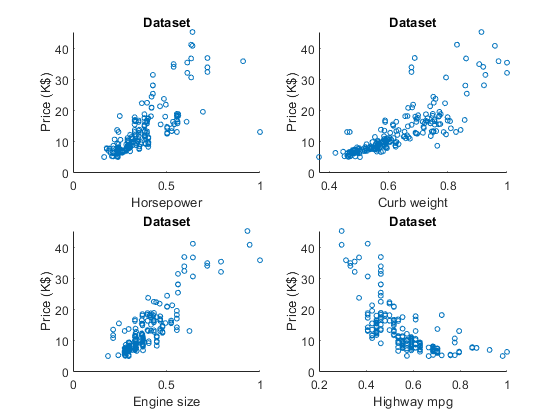

figure
h = subplot(2,2,1);
hold on
scatter(x1,y_points,h)
title('Dataset')
xlabel('Horsepower')
ylabel('Price (K$)')

subplot(2,2,2);
scatter(x2,y_points,h)
title('Dataset')
xlabel('Curb weight')
ylabel('Price (K$)')

subplot(2,2,3);
scatter(x3,y_points,h)
title('Dataset')
xlabel('Engine size')
ylabel('Price (K$)')

subplot(2,2,4);
scatter(x4,y_points,h)
title('Dataset')
xlabel('Highway mpg')
ylabel('Price (K$)')
hold off

Il modello viene addestrato attraverso il metodo del gradiente coniugato.

k_max = 100;        % numero massimo di iterazioni
toll = 1e-6;        % tolleranza richiesta
met = 'cg';         % metodo (gradiente o gradiente coniugato)
p0 = zeros(5,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p,res,iter,pvec,resvec] = multi_reg(x_points,y_points,k_max,toll,met,p0);

Completato l'addestramento del modello, vengono restituiti i coefficienti del polinomio dei minimi quadrati, conentuti nel vettore p.

p

p =    -3.5159
   32.9655
   15.4751
    5.2191
   -9.2394


 Ottenuti i coefficienti, è possibile stimare il prezzo di un'auto non contenuta all'interno del dataset.

x1_hat = 120/max(x1_temp);
x2_hat = 2500/max(x2_temp);
x3_hat = 155/max(x3_temp);
x4_hat = 28/max(x4_temp);
x_hat = [1 x1_hat x2_hat x3_hat x4_hat];

y_hat = x_hat*p

y_hat = 17.4253

### 3.1. Analisi dei risultati

Di seguito è possibile osservare l'andamento della norma dei residui calcolati durante l'esecuzione del metodo del gradiente coniugato, al variare del numero di iterazioni. Evidentemente, il metodo converge alla tolleranza specificata in 6 iterazioni. Il numero di iterazioni aumenta in quanto aumentano le dimensioni del sistema normale e con essa il numero di autovalori distinti della matrice.

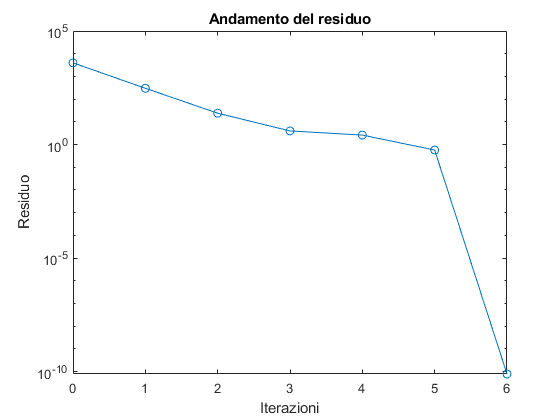

iter = 0:1:iter;
figure
semilogy(iter,resvec,'-o')
title('Andamento del residuo')
xlabel('Iterazioni')
ylabel('Residuo')

### 3.2. Confronto con il metodo del gradiente 

k_max = 100;        % numero massimo di iterazioni
toll = 1e-6;        % tolleranza richiesta
met = 'g';          % metodo (gradiente o gradiente coniugato)
p0 = zeros(5,1);    % coefficienti iniziali del polinomio dei minimi quadrati

[p_g,res_g,iter_g,pvec_g,resvec_g] = multi_reg(x_points,y_points,k_max,toll,met,p0);

È possibile osservare che utilizzando il metodo del gradiente tradizionale l'algoritmo non converge.

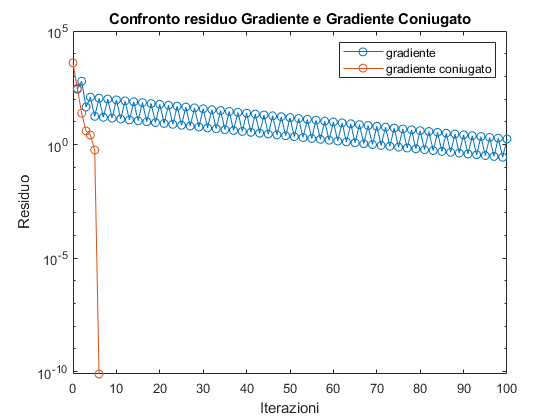

iter_g = 0:1:iter_g;
semilogy(iter_g,resvec_g,'-o')
hold on
semilogy(iter,resvec,'-o')
hold off

title('Confronto residuo Gradiente e Gradiente Coniugato')
xlabel('Iterazioni')
ylabel('Residuo')

legend('gradiente', 'gradiente coniugato')

## Autori

- d'Andrea Fabio      -     M63000989

- Daniele Dario         -     M63001026

- Di Chiara Guido     -     M63000986

- Iannucci Antimo     -     M63001040